clc;
clear;
close all;
tic

Load data from config file using load_config function

config = load_config('conf_file')


config =

  dictionary (string ⟼ cell) with 8 entries:

    "type"     ⟼ {'vblast'}
    "num_Tx"   ⟼ {'2'}
    "num_Rx"   ⟼ {'2'}
    "M"        ⟼ {'64'}
    "num_symb" ⟼ {'15000'}
    "points"   ⟼ {'10'}
    "ebn0_min" ⟼ {'8'}
    "ebn0_max" ⟼ {'18'}




num_Tx = str2num(config{'num_Tx'});
num_Rx = str2num(config{'num_Rx'});
eb_n0_min = str2num(config{'ebn0_min'});
eb_n0_max = str2num(config{'ebn0_max'});
points = str2num(config{'points'});
mod_Order = str2num(config{'M'});
num_symbols = str2num(config{'num_symb'});

## Leggi il contenuto del file output e plotta i risultati

TO DO: 

- calcolare il C.I. delle righe di ciascuna configurazione

- sistemare colori legenda

Apri, se esistono, tutti i file con la stessa configurazione attualmente specificata nel config file

% Read Zero forcing data
file_zf = strcat('output_', 'zf', '_', config{'num_Tx'}, '_', config{'num_Rx'}, '_', config{'ebn0_min'}, '_', ...
                    config{'ebn0_max'}, '_', config{'points'}, '_', config{'M'}, '_', config{'num_symb'}, '.txt');
if isfile(file_zf)
    ber_zf = readmatrix(file_zf);
    fclose('all');
end

% Read MMSE data
file_mmse = strcat('output_', 'mmse', '_', config{'num_Tx'}, '_', config{'num_Rx'}, '_', config{'ebn0_min'}, '_', ...
                    config{'ebn0_max'}, '_', config{'points'}, '_', config{'M'}, '_', config{'num_symb'}, '.txt');
if isfile(file_mmse)
    ber_mmse = readmatrix(file_mmse);
    fclose('all');
end

% Read vblast data
file_vblast = strcat('output_', 'vblast', '_', config{'num_Tx'}, '_', config{'num_Rx'}, '_', config{'ebn0_min'}, '_', ...
                    config{'ebn0_max'}, '_', config{'points'}, '_', config{'M'}, '_', config{'num_symb'}, '.txt');
if isfile(file_vblast)
    ber_vblast = readmatrix(file_vblast);
    fclose('all');
end

Compute 95 C.I.

% Definisci il livello di confidenza desiderato
confidence_level = 0.95;

% ---- ZF ---- %
if exist("ber_zf", "var")
    % Calcola CI
    ci_zf = calculate_confidence_intervals(ber_zf, confidence_level);
    % % disp('95% Confidence Intervals:');
    % % disp(ci_zf);
    % Calcola la media per ogni colonna
    mean_zf = mean(ber_zf);
end



% ---- MMSE ---- %
if exist("ber_mmse", "var")
    % Calcola CI
    ci_mmse = calculate_confidence_intervals(ber_mmse, confidence_level);
    % % disp('95% Confidence Intervals:');
    % % disp(ci_mmse);
    % Calcola la media per ogni colonna
    mean_mmse = mean(ber_mmse);
end


% ---- VBLAST ---- %
if exist("ber_vblast", "var")
    % Calcola CI
    ci_vblast = calculate_confidence_intervals(ber_vblast, confidence_level);
    % % disp('95% Confidence Intervals:');
    % % disp(ci_vblast);
    % Calcola la media per ogni colonna
    mean_vblast = mean(ber_vblast);
end

Plot the figures

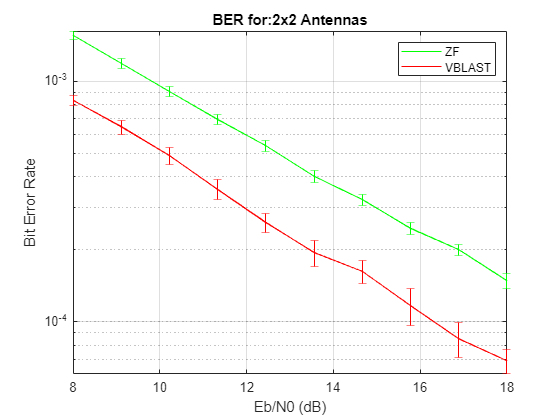

fig1 = figure;
leg = strings([1,3]);

% Plot zf if exists
if exist("ber_zf", "var")
    eb_n0 = linspace(eb_n0_min, eb_n0_max, length(mean_zf));
    % Plotta valori medi
    semilogy(eb_n0, mean_zf, 'g');
    hold on;
    % Plotta CI
    errorbar(eb_n0, mean_zf, mean_zf - ci_zf(:, 1)', ci_zf(:, 2)' - mean_zf, 'g');
    leg(1,1) = "ZF";
    hold on;
end

% Plot mmse if exists
if exist("ber_mmse", "var")
    eb_n0 = linspace(eb_n0_min, eb_n0_max, length(mean_mmse));
    % Plotta valori medi
    semilogy(eb_n0, mean_mmse, 'b');
    hold on;
    % Plotta CI
    errorbar(eb_n0, mean_mmse, mean_mmse - ci_mmse(:, 1)', ci_mmse(:, 2)' - mean_mmse, 'b');
    leg(1,2) = "MMSE";
    hold on;
end

% Plot vblast if exists
if exist("ber_vblast", "var")
    eb_n0 = linspace(eb_n0_min, eb_n0_max, length(mean_vblast));
    % Plotta valori medi
    semilogy(eb_n0, mean_vblast, 'r');
    hold on;
    % Plotta CI
    errorbar(eb_n0, mean_vblast, mean_vblast - ci_vblast(:, 1)', ci_vblast(:, 2)' - mean_vblast, 'r');
    leg(1,3) = "VBLAST";
end

hold off;
legend(leg(1), leg(2), leg(3))
title({ strcat('BER for: ', num2str(num_Tx), 'x' , num2str(num_Rx), ' Antennas')})
xlabel('Eb/N0 (dB)');
ylabel('Bit Error Rate');
grid on

Plot the figures

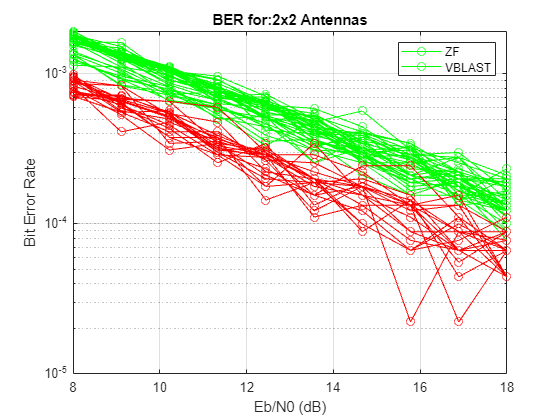

fig2 = figure;
leg = strings([1,3]);

% Plot zf if exists
if exist("ber_zf", "var")
    eb_n0 = linspace(eb_n0_min, eb_n0_max, length(ber_zf(1, :)));
    semilogy(eb_n0, ber_zf, 'g-o');
    leg(1,1) = "ZF";
    hold on;
end

% Plot mmse if exists
if exist("ber_mmse", "var")
    eb_n0 = linspace(eb_n0_min, eb_n0_max, length(ber_mmse(1, :)));
    semilogy(eb_n0, ber_mmse, 'b-o');
    leg(1,2) = "MMSE";
    hold on;
end

% Plot vblast if exists
if exist("ber_vblast", "var")
    eb_n0 = linspace(eb_n0_min, eb_n0_max, length(ber_vblast(1, :)));
    semilogy(eb_n0, ber_vblast, 'r-o');
    leg(1,3) = "VBLAST";
end

hold off;
legend(leg(1), leg(2), leg(3))
title({ strcat('BER for: ', num2str(num_Tx), 'x' , num2str(num_Rx), ' Antennas')})
xlabel('Eb/N0 (dB)');
ylabel('Bit Error Rate');
grid on

Print execution time

toc

Elapsed time is 0.317429 seconds.


function [ci] = calculate_confidence_intervals(data, confidence_level)
    % Calcola l'intervallo di confidenza per ogni elemento della colonna nella matrice data
    % data: matrice (vettore di vettori) contenente i dati
    % confidence_level: livello di confidenza desiderato (es. 0.95 per il 95% CI)

    % Calcola il numero di colonne nella matrice data
    num_columns = size(data, 2);

    % Inizializza il vettore per contenere i vari CI
    ci = zeros(num_columns, 2);

    % Calcola il valore critico basato sul confidence interval
    % Utilizzando la distribuzione normale std
    z_critical = norminv(1 - (1 - confidence_level) / 2);

    % Calcola CI per ogni elemento della colonna
    for j = 1:num_columns
        % Calcola la media della colonna
        mean_value = mean(data(:, j));

        % Calcola la deviazione standard della colonna
        std_dev = std(data(:, j));

        % Calcola numero di righe
        n = size(data, 1);

        % Calcola l'errore standard della media
        std_error = std_dev / sqrt(n);

        % Calcola il CI
        conf_interval = z_critical * std_error;

        % Calcola gli estremi del CI
        lower_bound = mean_value - conf_interval;
        upper_bound = mean_value + conf_interval;

        % Salva gli estremi del CI nella matrice
        ci(j, :) = [lower_bound, upper_bound];
    end
end
